**Opening the raw EEG data into Matlab. **

data = load('Lab2_Hw2_Raw_Data.mat');

**Describe the data structure used to record the EEG signals.**

fieldnames(data)

ans = 1×1 cell array
    {'y'}


EEG = data.y;
size(EEG)

ans =            5       46081


The field is a matrix with size 5 x 46081, where the first dimension should correspond to 5 recorded signals ( the 4 EEG channels we actually wanted to record from plus one sample counter) and the second dimension corresponds to time.

**1. Plot the raw EEG signals (Noise included)**

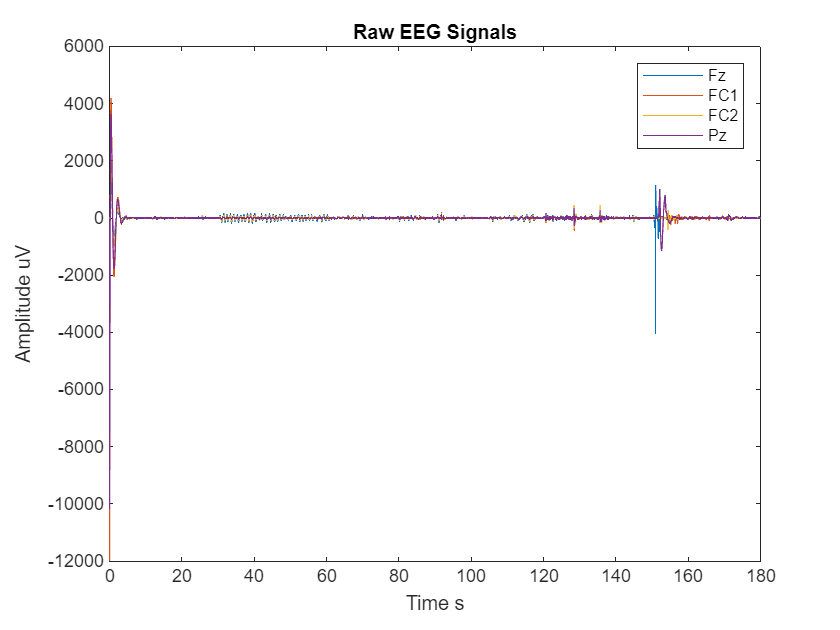

% Extract EEG channels (we should skip first row, since this is the counter)
EEG = data.y(2:5, :);

%sampling rate and time Vector 
fs = 256;              % Hz
t = (0:size(EEG,2)-1) / fs;   % just get that time V in seconds 

%look at the raw signals 
figure;
plot(t, EEG');
xlabel('Time s');
ylabel('Amplitude uV');
title('Raw EEG Signals');
legend({'Fz','FC1','FC2','Pz'});

**Now lets remove the DC component:**

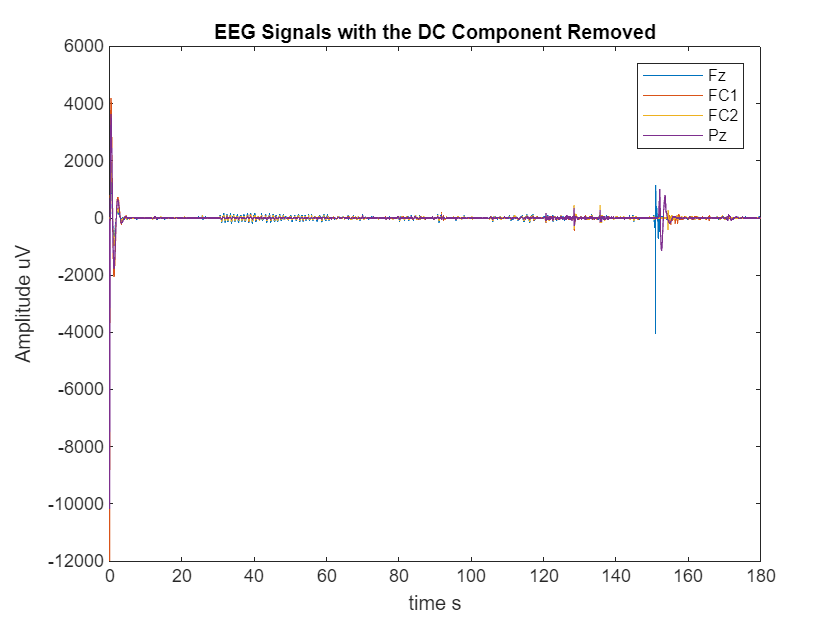

% Remove the DC offset by subtracting the mean value from each of the
% channels.
EEG_detrended = EEG - mean(EEG, 2);

%compare the two (not much difference, 
figure;
plot(t, EEG_detrended');
xlabel('time s');
ylabel('Amplitude uV');
title('EEG Signals with the DC Component Removed');
legend({'Fz','FC1','FC2','Pz'});

**3. Design filters for Alpha (8-13Hz) and Beta (14-32Hz) frequencies. Report**

**the power in each band during conditions A-F. You can design your own filter**

**or use eegfilt.m from EEGLAB (available on Courseworks).**

EEG_proc = EEG_detrended;   % should still only have the channels that we are interested in
fs = 256;

% applying all of the filters" butterworth bandstop, notch @ 60Hz

[bn, an] = butter(2, [59 61]/(fs/2), 'stop');

% getting the waves: alpha @ 8–13 Hz, beta @ 14–32 Hz
[ba, aa] = butter(4, [8 13]/(fs/2));
[bb, ab] = butter(4, [14 32]/(fs/2));

% epoching per all conditions of experiment (6 × 30 s)
segment_len = 30*fs;
nCond = 6;
cond_names = {'Silent','Blinking','RollingEyes','Chewing','NeckTense','TouchElectrodes'};

% zereos to store results 
alpha_power = zeros(size(EEG_proc,1), nCond);
beta_power  = zeros(size(EEG_proc,1), nCond);

% that winsorizing hyperparameter that we need in order to get rid of that one really bad artifact (robust z ~ k*MAD)
k = 6;  % larger is less aggressive, might have to change to 5. Controls how aggressively the winsorizing step is going to clips outliers

for c = 1:nCond
    idx1 = (c-1)*segment_len + 1;
    idx2 = c*segment_len;

    % take the broadband segment that we made and then notch first
    seg_bb = double(EEG_proc(:, idx1:idx2));
    seg_bb = filtfilt(bn, an, seg_bb')';   % notch occuring per channel

    % here is our robust winsorizing per channel
    % caps the values to be outside (median ± k*MAD)
    m  = median(seg_bb, 2);
    madv = median(abs(seg_bb - m), 2) + eps;
    lower = m - k.*madv;
    upper = m + k.*madv;
    seg_w = seg_bb;
    for ch = 1:size(seg_bb,1)
        seg_w(ch,:) = min(max(seg_bb(ch,:), lower(ch)), upper(ch));
    end

    %now time for the bandpass and the to compute the bpower (as mean-square)
    seg_alpha = filtfilt(ba, aa, seg_w')';
    seg_beta  = filtfilt(bb, ab, seg_w')';

    alpha_power(:,c) = mean(seg_alpha.^2, 2);
    beta_power(:,c)  = mean(seg_beta.^2,  2);
end

%table generation
disp('Alpha Band Power (uV^2) by Condition and Channel (winsorized for abnormal silent condition):')

Alpha Band Power (uV^2) by Condition and Channel (winsorized for abnormal silent condition):


alpha_tbl = array2table(alpha_power', 'VariableNames', {'Fz','FC1','FC2','Pz'}, ...
                        'RowNames', cond_names)

alpha_tbl = 6×4 table
                         Fz       FC1       FC2        Pz  
                       ______    ______    ______    ______

    Silent             11.393    11.483    10.586    8.7297
    Blinking           16.413    14.941    15.655    20.547
    RollingEyes        10.151    9.8688    10.047    10.567
    Chewing            12.762    13.798    13.122    15.963
    NeckTense          18.777    18.978     19.43    22.589
    TouchElectrodes    18.923    17.896    11.052    11.025



disp('Beta Band Power (uV^2) by Condition and Channel (winsorized for abnormal silent condition):')

Beta Band Power (uV^2) by Condition and Channel (winsorized for abnormal silent condition):


beta_tbl = array2table(beta_power', 'VariableNames', {'Fz','FC1','FC2','Pz'}, ...
                       'RowNames', cond_names)

beta_tbl = 6×4 table
                         Fz       FC1       FC2        Pz  
                       ______    ______    ______    ______

    Silent             15.757    15.646    15.816    13.959
    Blinking           15.451    13.462     15.01    11.053
    RollingEyes        16.741    16.509    16.679    14.891
    Chewing            21.701    23.043    22.444    18.114
    NeckTense          93.353    94.525    100.04    81.918
    TouchElectrodes    24.892    18.879    18.335    14.029


Specific filters that were chosen:

- A 60 Hz notch bandstop filter that removes the power line interference.

- Two separate Butterworth bandpass filters to isolate the both alpha and beta band.

Then we apply segmentation to the recording, and divide the recording into 6 equal 30 second recordings that correspond to each condition in the experiment. 

To avoid one large spike overwhelming the averages (you can see the large spike in the first couple seconds of the raw waveform), I opted to apply winsorizing (which is essentially just clipping values based on a median absolute deviation threshold). 

MAD = median absolute deviation

[median−k⋅MAD,median+k⋅MAD]

I believe traditionally I could have just cut the first couple seconds of the recording, but that would have messed with the aforementioned segmentation. This winsorizing helps reduce the influence of extreme outliers without discarding the entire epoch. Without winsorizing, the alpha and beta powers were around 1,277, and after winsorizing was applied the powers dropped to a more resonable value. 

For each of the segments and channels, the mean squared amplitude of the filtered signals is then computed and output to a table. 